We are at interation 1
We are at interation 2
We are at interation 3
We are at interation 4
We are at interation 5
We are at interation 6
We are at interation 7
We are at interation 8
We are at interation 9
We are at interation 10
We are at interation 11
We are at interation 12
We are at interation 13
We are at interation 14
We are at interation 15
We are at interation 16
We are at interation 17
We are at interation 18


result = 3.1416

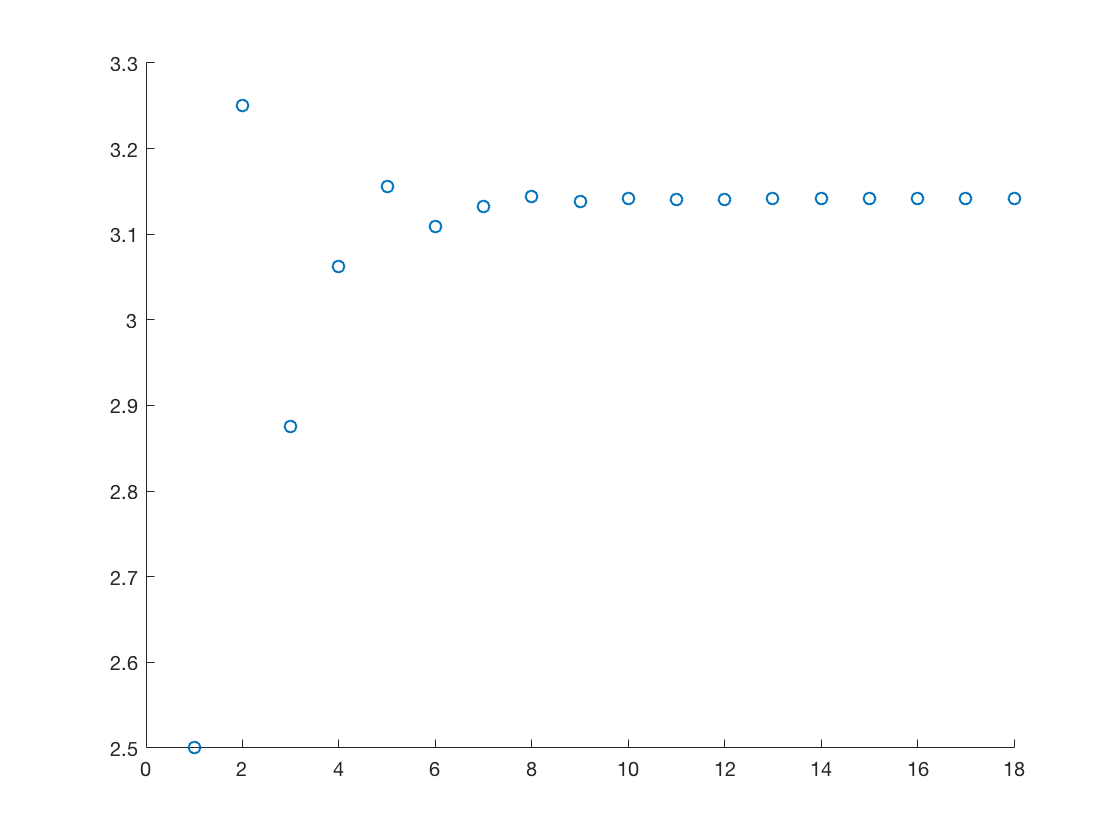

ans = 3.1416

%Number 1A
f = @(x) sin(x);
a = 1;
b = 4;
tol = 0.00002;
maxits = 30;

assert(sign(f(a)) ~= sign(f(b)));
assert(a<b);
assert(~isinf(a) && ~isinf(b));

bisection(f,a,b,tol,maxits)

% 3.14159
% The tolerance has to be relatively low
% tol < 0.00002 to get an accurate reading
% Takes about 17 iterations to get the 
% first 6 desired digits

We are at interation 1
We are at interation 2
We are at interation 3
We are at interation 4
We are at interation 5
We are at interation 6
We are at interation 7
We are at interation 8
We are at interation 9
We are at interation 10
We are at interation 11
We are at interation 12
We are at interation 13


result = 1.5707

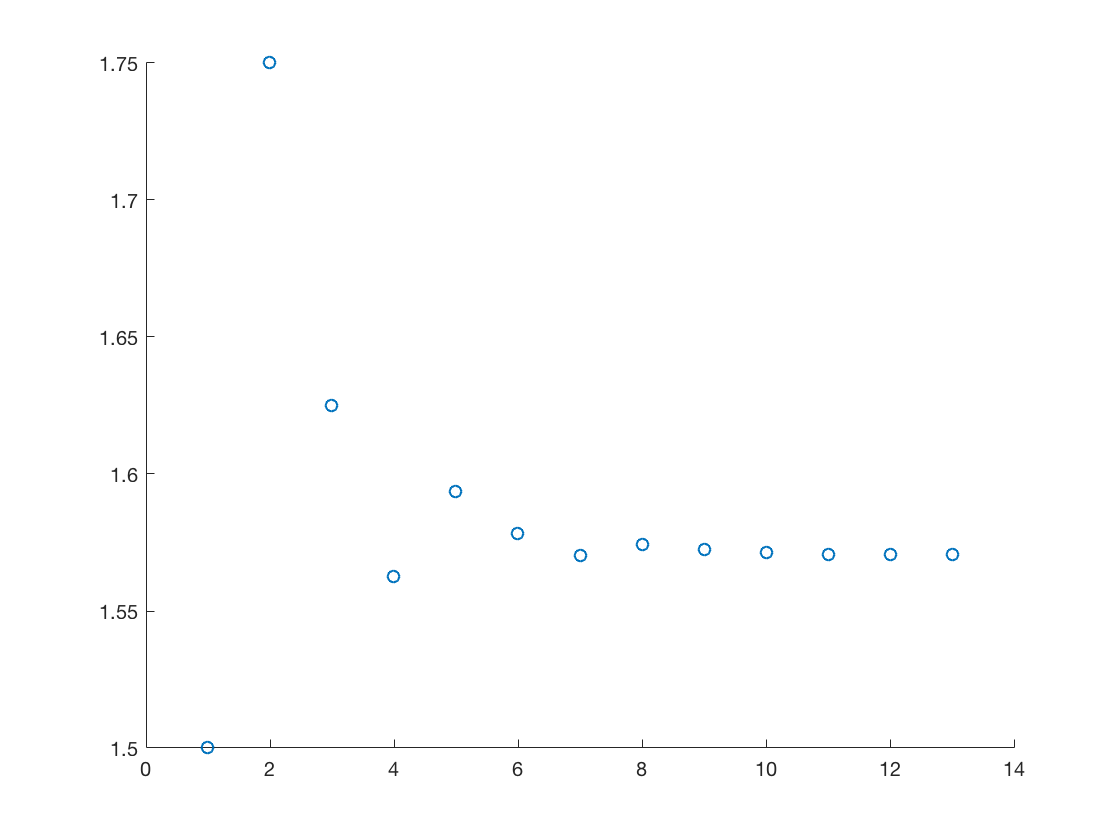

ans = 1.5707

%Number 1B
f = @(x) tan(x);
a = 1;
b = 2;
tol = 0.0002;
maxits = 20;

assert(sign(f(a)) ~= sign(f(b)));
assert(a<b);
assert(~isinf(a) && ~isinf(b));

bisection(f,a,b,tol,maxits)

%1.570
% Similar to number 1, the tol
% has to be fairly low to get
% an accurate reading. 1.570 is
% about the root. Takes about 10
% iterations

% Number 2A
fzero(@sin,[1,4])

ans = 3.1416

% 3.141592653589793
% This has all the digits correct

%Number 2B
fzero(@tan, [1 2]);
fzero(@tan, [1 2], optimset('Display','iter'));

 
 Func-count    x          f(x)             Procedure
    2               1       1.55741        initial
    3               2      -2.18504        interpolation
    4         1.85165      -3.46644        interpolation
    5         1.41615        6.4146        bisection
    6         1.47895       10.8572        interpolation
    7          1.6339      -15.8261        bisection
    8         1.61954      -20.4982        interpolation
    9         1.58798      -58.1765        bisection
   10         1.55642       69.5775        bisection
   11         1.55783       77.1347        interpolation
   12         1.56502       173.074        bisection
   13         1.56861       457.679        bisection
   14          1.5722      -710.251        bisection
   15         1.57182       -980.91        interpolation
   16         1.57041       2574.06        bisection
   17         1.57111      -3169.73        interpolation
   18         1.57104      -4124.11        interpolation
   19         

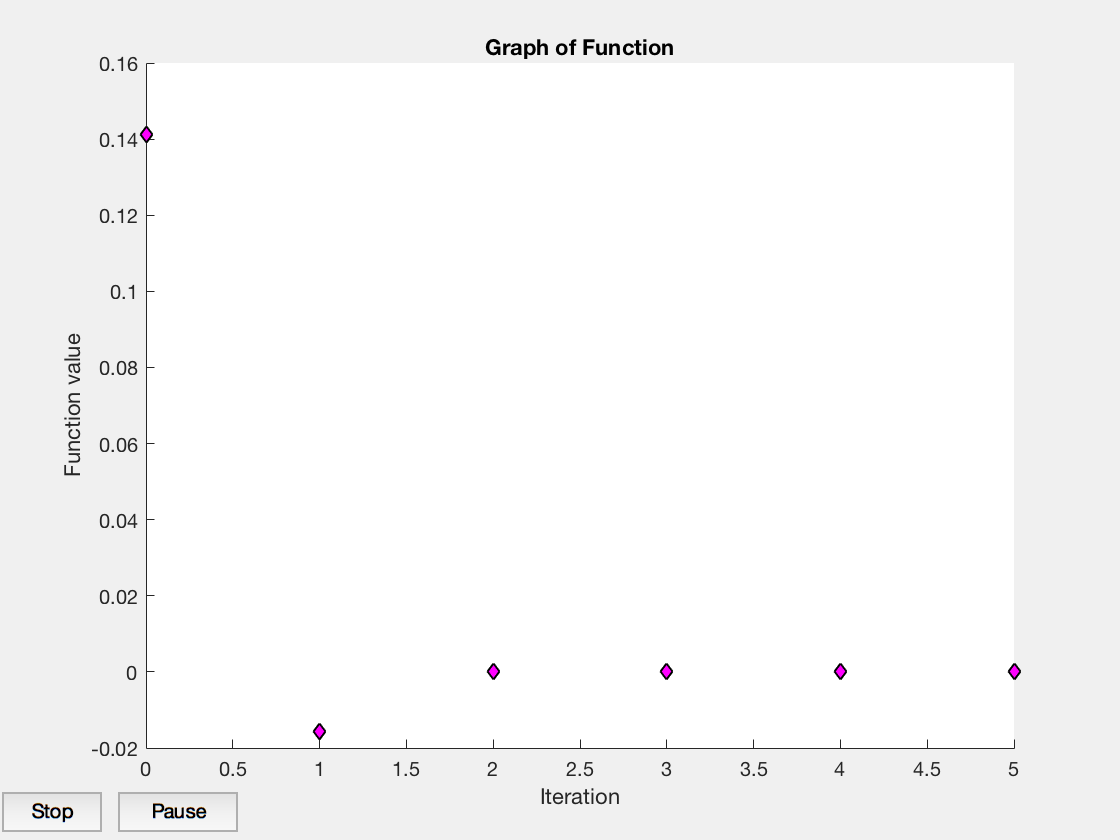

%Number 2C
fzero(@sin, [3 4], optimset('PlotFcns',@optimplotfval));
title('Graph of Function');

We are at interation 1
We are at interation 2
We are at interation 3
We are at interation 4
We are at interation 5
We are at interation 6
We are at interation 7
We are at interation 8
We are at interation 9
We are at interation 10
We are at interation 11
We are at interation 12
We are at interation 13


result = 1.5707

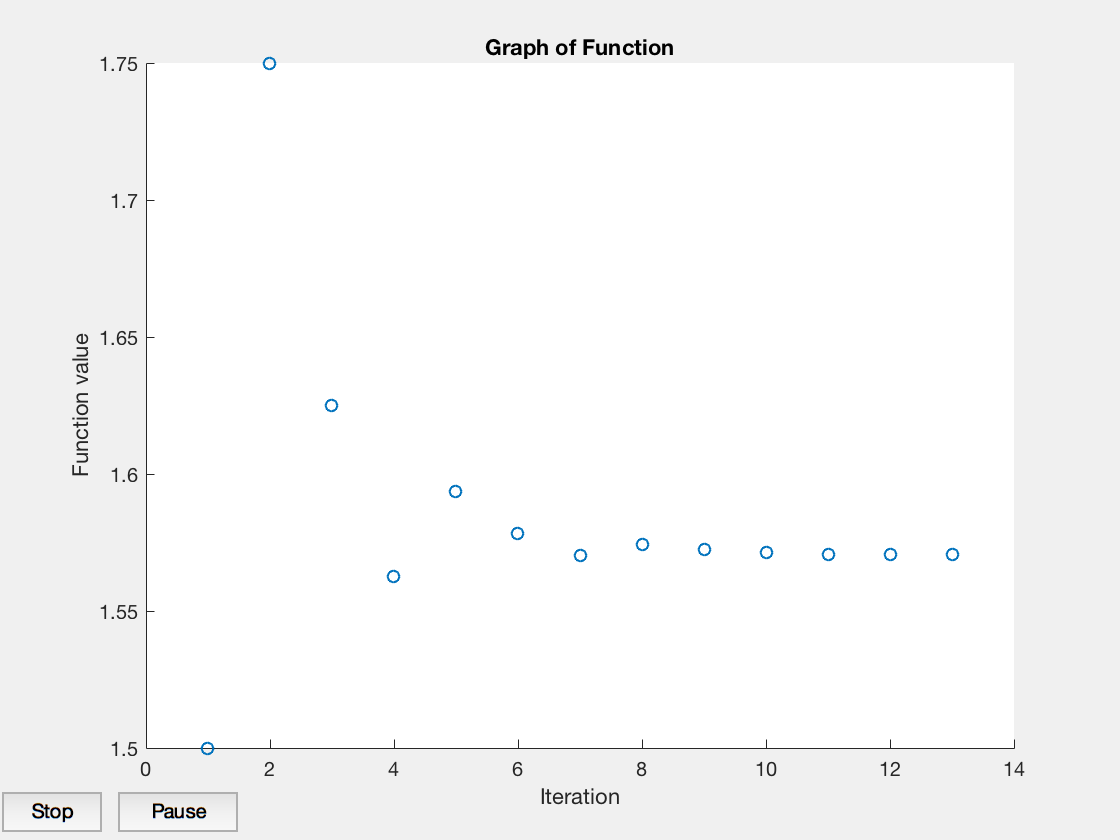

%Number 2D
%Update the function
bisection(f,a,b,tol,maxits,'inter');

function result = bisection(f, a, b, tol, maxits, iter)
% f is function
% a,b is the interval
% tol is the tolerance before we encounter an error (27)
% maxits is the number of ints allowed
    
    %fzero(f, [a b]);
    %fzero(f, [a b], optimset('Display','iter'))
    %fzero(f, [a b], optimset('PlotFcns', @optimplotfval))
    
    if (f(a) == 0)
        result = a;
        return;
    elseif f(b) == 0
        result = b;
        return;
    end
    
    x = 0;
    y = 0;
    
    for i=1:maxits
        fprintf("We are at interation "+ i + "\n");
        c = (a+b)/2;
        x(i) = i;
        y(i) = c;
        if f(c) == 0 || (b-a)/2 < tol
           result = c
           break;
        end
        if sign(f(c)) ~= sign(f(a))
            %print(root if left of the subinterval)
            b = c; %a stays unchanged
        else 
            a = c; %b stays unchanged
        end
            
        result = c;
    end
        if ((b-a)/2 > tol)
            fprintf("We're going to need more iterations!");
        end
        title('Graph of Function');
        scatter(x, y);
        
end